% get commit list
start_date = '2024-05-23';
end_date = '2025-04-02'

end_date = '2025-04-02'

git_cmd = strcat("git rev-list --pretty=%h%ad --date=short --since=", start_date, " --until=",end_date," HEAD");
[~, commit_list_str] = system(git_cmd);
commit_list_cell = splitlines(commit_list_str);
commit_list_cell = commit_list_cell(2:2:end-1);

hash_cell = cellfun(@(s) s(1:min(7, end)), commit_list_cell, 'UniformOutput', false);
date_cell = cellfun(@(s) s(8:end),         commit_list_cell, 'UniformOutput', false);

% make empty variables
hydro_error = nan(4,length(commit_list_cell));

% Set your GitHub Personal Access Token (PAT) or use GitHub Action's GITHUB_TOKEN
GITHUB_TOKEN = fileread('github_token');

% Define options for the web request (including authentication header)
options = weboptions('HeaderFields', {'Authorization', ['token ' GITHUB_TOKEN]}, ...
                     'ContentType', 'json', 'Timeout', 30);

repo_url = 'https://api.github.com/repos/symbiotic-engineering/MDOcean/';

N = length(commit_list_cell);


for idx_commit=1:N
    fprintf('Getting CI data for commit %d of %d\n', idx_commit, N)

    commit_sha = hash_cell{idx_commit};
    % Define the URL to fetch check runs
    url = [repo_url sprintf('commits/%s/check-runs', commit_sha)];
    
    % Send the GET request to GitHub API
    response = webread(url, options);
    
    % Parse the check runs from the response
    check_runs = response.check_runs;

    if ~isempty(check_runs)
        idx_junit = strcmp({check_runs.name},'JUnit Test Report');
        if any(idx_junit)
            id = num2str(check_runs(idx_junit).id);
        
            url_2 = [repo_url 'check-runs/' id '/annotations'];
            annotations = webread(url_2, options);
        
            if ~isempty(annotations)
                idx_hydro = contains({annotations.title},'test.validateNominalHydroCoeffs');
            
                setup_failed = contains({annotations.message},'Error occurred while setting up or tearing down test.');

                if any(idx_hydro & ~setup_failed)
                    hydro_error(:,idx_commit) = extract_actual_value(annotations(idx_hydro).raw_details);
                end
            end
        end
    end

end

Getting CI data for commit 1 of 729


idx_hydro = 1×15 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 2 of 729


idx_hydro = 1×16 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 3 of 729
Getting CI data for commit 4 of 729
Getting CI data for commit 5 of 729
Getting CI data for commit 6 of 729
Getting CI data for commit 7 of 729
Getting CI data for commit 8 of 729
Getting CI data for commit 9 of 729
Getting CI data for commit 10 of 729
Getting CI data for commit 11 of 729


idx_hydro = 1×17 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 12 of 729
Getting CI data for commit 13 of 729
Getting CI data for commit 14 of 729
Getting CI data for commit 15 of 729


idx_hydro = 1×24 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 16 of 729


idx_hydro = 1×24 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 17 of 729
Getting CI data for commit 18 of 729


idx_hydro = 1×17 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 19 of 729


idx_hydro = 1×24 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 20 of 729


idx_hydro = 1×21 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 21 of 729


idx_hydro = 1×21 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 22 of 729


idx_hydro = 1×21 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 23 of 729
Getting CI data for commit 24 of 729
Getting CI data for commit 25 of 729


idx_hydro = 1×19 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 26 of 729


idx_hydro = 1×18 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 27 of 729
Getting CI data for commit 28 of 729


idx_hydro = 1×19 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 29 of 729
Getting CI data for commit 30 of 729
Getting CI data for commit 31 of 729
Getting CI data for commit 32 of 729


idx_hydro = 1×22 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 33 of 729


idx_hydro = 1×22 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 34 of 729


idx_hydro = 1×22 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 35 of 729


idx_hydro = 1×21 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 36 of 729


idx_hydro = 1×21 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 37 of 729


idx_hydro = 1×24 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 38 of 729


idx_hydro = 1×24 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 39 of 729
Getting CI data for commit 40 of 729


idx_hydro = 1×24 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 41 of 729


idx_hydro = 1×24 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 42 of 729
Getting CI data for commit 43 of 729
Getting CI data for commit 44 of 729
Getting CI data for commit 45 of 729


idx_hydro = 1×24 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 46 of 729


idx_hydro = 1×24 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 47 of 729
Getting CI data for commit 48 of 729


idx_hydro = 1×24 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 49 of 729
Getting CI data for commit 50 of 729
Getting CI data for commit 51 of 729
Getting CI data for commit 52 of 729
Getting CI data for commit 53 of 729
Getting CI data for commit 54 of 729
Getting CI data for commit 55 of 729
Getting CI data for commit 56 of 729
Getting CI data for commit 57 of 729
Getting CI data for commit 58 of 729
Getting CI data for commit 59 of 729


idx_hydro = 1×21 logical array
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 60 of 729
Getting CI data for commit 61 of 729
Getting CI data for commit 62 of 729
Getting CI data for commit 63 of 729
Getting CI data for commit 64 of 729
Getting CI data for commit 65 of 729


idx_hydro = 1×20 logical array
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 66 of 729
Getting CI data for commit 67 of 729


idx_hydro = 1×20 logical array
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 68 of 729


idx_hydro = 1×25 logical array
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 69 of 729
Getting CI data for commit 70 of 729
Getting CI data for commit 71 of 729


idx_hydro = 1×22 logical array
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 72 of 729
Getting CI data for commit 73 of 729


idx_hydro = 1×21 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 74 of 729


idx_hydro = 1×21 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 75 of 729


idx_hydro = 1×21 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 76 of 729


idx_hydro = 1×28 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 77 of 729


idx_hydro = 1×28 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 78 of 729
Getting CI data for commit 79 of 729
Getting CI data for commit 80 of 729
Getting CI data for commit 81 of 729
Getting CI data for commit 82 of 729
Getting CI data for commit 83 of 729
Getting CI data for commit 84 of 729
Getting CI data for commit 85 of 729
Getting CI data for commit 86 of 729
Getting CI data for commit 87 of 729
Getting CI data for commit 88 of 729
Getting CI data for commit 89 of 729
Getting CI data for commit 90 of 729
Getting CI data for commit 91 of 729
Getting CI data for commit 92 of 729
Getting CI data for commit 93 of 729
Getting CI data for commit 94 of 729
Getting CI data for commit 95 of 729
Getting CI data for commit 96 of 729
Getting CI data for commit 97 of 729
Getting CI data for commit 98 of 729
Getting CI data for commit 99 of 729
Getting CI data for commit 100 of 729
Getting CI data for commit 101 of 729


idx_hydro = 1×21 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 102 of 729


idx_hydro = 1×22 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 103 of 729


idx_hydro = 1×22 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 104 of 729


idx_hydro = 1×22 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 105 of 729
Getting CI data for commit 106 of 729
Getting CI data for commit 107 of 729
Getting CI data for commit 108 of 729


idx_hydro = 1×27 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 109 of 729


idx_hydro = 1×20 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 110 of 729


idx_hydro = 1×20 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 111 of 729
Getting CI data for commit 112 of 729


idx_hydro = 1×20 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 113 of 729
Getting CI data for commit 114 of 729


idx_hydro = 1×15 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 115 of 729
Getting CI data for commit 116 of 729


idx_hydro = 1×15 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 117 of 729


idx_hydro = 1×15 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 118 of 729


idx_hydro = 1×15 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 119 of 729


idx_hydro = 1×15 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 120 of 729


idx_hydro = 1×15 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 121 of 729
Getting CI data for commit 122 of 729


idx_hydro = 1×15 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 123 of 729


idx_hydro = 1×22 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 124 of 729
Getting CI data for commit 125 of 729
Getting CI data for commit 126 of 729
Getting CI data for commit 127 of 729
Getting CI data for commit 128 of 729
Getting CI data for commit 129 of 729


idx_hydro = 1×22 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 130 of 729


idx_hydro = 1×22 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 131 of 729


idx_hydro = 1×18 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 132 of 729
Getting CI data for commit 133 of 729
Getting CI data for commit 134 of 729


idx_hydro = 1×18 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 135 of 729
Getting CI data for commit 136 of 729


idx_hydro = 1×18 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 137 of 729
Getting CI data for commit 138 of 729


idx_hydro = 1×18 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 139 of 729
Getting CI data for commit 140 of 729


idx_hydro = 1×20 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 141 of 729
Getting CI data for commit 142 of 729


idx_hydro = 1×21 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 143 of 729


idx_hydro = 1×21 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 144 of 729
Getting CI data for commit 145 of 729


idx_hydro = 1×25 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 146 of 729
Getting CI data for commit 147 of 729


idx_hydro = 1×26 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 148 of 729


idx_hydro = 1×26 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 149 of 729


idx_hydro = 1×26 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 150 of 729


idx_hydro = 1×26 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 151 of 729
Getting CI data for commit 152 of 729


idx_hydro = 1×21 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 153 of 729
Getting CI data for commit 154 of 729
Getting CI data for commit 155 of 729
Getting CI data for commit 156 of 729


idx_hydro = 1×26 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 157 of 729
Getting CI data for commit 158 of 729
Getting CI data for commit 159 of 729
Getting CI data for commit 160 of 729


idx_hydro = 1×26 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 161 of 729


idx_hydro = 1×28 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 162 of 729


idx_hydro = 1×28 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 163 of 729


idx_hydro = 1×28 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 164 of 729
Getting CI data for commit 165 of 729


idx_hydro = 1×30 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 166 of 729


idx_hydro = 1×30 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 167 of 729


idx_hydro = 1×30 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 168 of 729


idx_hydro = 1×18 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 169 of 729
Getting CI data for commit 170 of 729
Getting CI data for commit 171 of 729


idx_hydro = 1×18 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 172 of 729
Getting CI data for commit 173 of 729
Getting CI data for commit 174 of 729
Getting CI data for commit 175 of 729
Getting CI data for commit 176 of 729
Getting CI data for commit 177 of 729
Getting CI data for commit 178 of 729
Getting CI data for commit 179 of 729
Getting CI data for commit 180 of 729
Getting CI data for commit 181 of 729
Getting CI data for commit 182 of 729
Getting CI data for commit 183 of 729
Getting CI data for commit 184 of 729
Getting CI data for commit 185 of 729
Getting CI data for commit 186 of 729
Getting CI data for commit 187 of 729
Getting CI data for commit 188 of 729


idx_hydro = 1×15 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 189 of 729
Getting CI data for commit 190 of 729


idx_hydro = 1×16 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 191 of 729


idx_hydro = 1×15 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 192 of 729


idx_hydro = 1×14 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 193 of 729
Getting CI data for commit 194 of 729
Getting CI data for commit 195 of 729
Getting CI data for commit 196 of 729
Getting CI data for commit 197 of 729
Getting CI data for commit 198 of 729
Getting CI data for commit 199 of 729
Getting CI data for commit 200 of 729
Getting CI data for commit 201 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 202 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 203 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 204 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 205 of 729
Getting CI data for commit 206 of 729
Getting CI data for commit 207 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 208 of 729


idx_hydro = 1×14 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 209 of 729
Getting CI data for commit 210 of 729
Getting CI data for commit 211 of 729


idx_hydro = 1×14 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 212 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 213 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 214 of 729
Getting CI data for commit 215 of 729


idx_hydro = 1×14 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 216 of 729
Getting CI data for commit 217 of 729
Getting CI data for commit 218 of 729


idx_hydro = 1×19 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 219 of 729


idx_hydro = 1×19 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 220 of 729
Getting CI data for commit 221 of 729


idx_hydro = 1×14 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 222 of 729
Getting CI data for commit 223 of 729
Getting CI data for commit 224 of 729
Getting CI data for commit 225 of 729


idx_hydro = 1×13 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 226 of 729
Getting CI data for commit 227 of 729
Getting CI data for commit 228 of 729


idx_hydro = 1×14 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 229 of 729
Getting CI data for commit 230 of 729
Getting CI data for commit 231 of 729
Getting CI data for commit 232 of 729
Getting CI data for commit 233 of 729
Getting CI data for commit 234 of 729
Getting CI data for commit 235 of 729
Getting CI data for commit 236 of 729
Getting CI data for commit 237 of 729
Getting CI data for commit 238 of 729
Getting CI data for commit 239 of 729
Getting CI data for commit 240 of 729
Getting CI data for commit 241 of 729
Getting CI data for commit 242 of 729
Getting CI data for commit 243 of 729


idx_hydro = 1×13 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 244 of 729
Getting CI data for commit 245 of 729
Getting CI data for commit 246 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 247 of 729


idx_hydro = 1×12 logical array
   0   0   1   0   0   0   0   0   0   0   0   0


Getting CI data for commit 248 of 729


idx_hydro = 1×16 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 249 of 729
Getting CI data for commit 250 of 729
Getting CI data for commit 251 of 729


idx_hydro = 1×22 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 252 of 729


idx_hydro = 1×22 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 253 of 729
Getting CI data for commit 254 of 729


idx_hydro = 1×21 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 255 of 729
Getting CI data for commit 256 of 729
Getting CI data for commit 257 of 729
Getting CI data for commit 258 of 729


idx_hydro = 1×12 logical array
   0   0   1   0   0   0   0   0   0   0   0   0


Getting CI data for commit 259 of 729
Getting CI data for commit 260 of 729


idx_hydro = 1×12 logical array
   0   0   1   0   0   0   0   0   0   0   0   0


Getting CI data for commit 261 of 729


idx_hydro = 1×12 logical array
   0   0   1   0   0   0   0   0   0   0   0   0


Getting CI data for commit 262 of 729
Getting CI data for commit 263 of 729


idx_hydro = 1×18 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 264 of 729


idx_hydro = 1×18 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 265 of 729
Getting CI data for commit 266 of 729


idx_hydro = 1×13 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 267 of 729


idx_hydro = 1×12 logical array
   0   0   1   0   0   0   0   0   0   0   0   0


Getting CI data for commit 268 of 729


idx_hydro = 1×12 logical array
   0   0   1   0   0   0   0   0   0   0   0   0


Getting CI data for commit 269 of 729


idx_hydro = 1×12 logical array
   0   0   1   0   0   0   0   0   0   0   0   0


Getting CI data for commit 270 of 729
Getting CI data for commit 271 of 729
Getting CI data for commit 272 of 729
Getting CI data for commit 273 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 274 of 729
Getting CI data for commit 275 of 729
Getting CI data for commit 276 of 729
Getting CI data for commit 277 of 729


idx_hydro = 1×16 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 278 of 729


idx_hydro = 1×16 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 279 of 729
Getting CI data for commit 280 of 729
Getting CI data for commit 281 of 729


idx_hydro = 1×13 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 282 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 283 of 729
Getting CI data for commit 284 of 729
Getting CI data for commit 285 of 729


idx_hydro = 1×13 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 286 of 729
Getting CI data for commit 287 of 729
Getting CI data for commit 288 of 729
Getting CI data for commit 289 of 729


idx_hydro = 1×13 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 290 of 729


idx_hydro = 1×13 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 291 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 292 of 729
Getting CI data for commit 293 of 729
Getting CI data for commit 294 of 729
Getting CI data for commit 295 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 296 of 729
Getting CI data for commit 297 of 729


idx_hydro = 1×10 logical array
   0   0   1   0   0   0   0   0   0   0


Getting CI data for commit 298 of 729
Getting CI data for commit 299 of 729
Getting CI data for commit 300 of 729


idx_hydro = 1×10 logical array
   0   0   1   0   0   0   0   0   0   0


Getting CI data for commit 301 of 729
Getting CI data for commit 302 of 729
Getting CI data for commit 303 of 729
Getting CI data for commit 304 of 729


idx_hydro = 1×10 logical array
   0   0   1   0   0   0   0   0   0   0


Getting CI data for commit 305 of 729
Getting CI data for commit 306 of 729
Getting CI data for commit 307 of 729
Getting CI data for commit 308 of 729


idx_hydro = 1×10 logical array
   0   0   1   0   0   0   0   0   0   0


Getting CI data for commit 309 of 729


idx_hydro = 1×8 logical array
   0   0   1   0   0   0   0   0


Getting CI data for commit 310 of 729
Getting CI data for commit 311 of 729
Getting CI data for commit 312 of 729
Getting CI data for commit 313 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 314 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 315 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 316 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 317 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 318 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 319 of 729


idx_hydro = 1×19 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 320 of 729


idx_hydro = 1×19 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 321 of 729
Getting CI data for commit 322 of 729


idx_hydro = 1×25 logical array
   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 323 of 729


idx_hydro = 1×17 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 324 of 729
Getting CI data for commit 325 of 729
Getting CI data for commit 326 of 729
Getting CI data for commit 327 of 729
Getting CI data for commit 328 of 729


idx_hydro = 1×17 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 329 of 729
Getting CI data for commit 330 of 729
Getting CI data for commit 331 of 729
Getting CI data for commit 332 of 729


idx_hydro = 1×10 logical array
   0   0   1   0   0   0   0   0   0   0


Getting CI data for commit 333 of 729
Getting CI data for commit 334 of 729
Getting CI data for commit 335 of 729


idx_hydro = 1×10 logical array
   0   0   1   0   0   0   0   0   0   0


Getting CI data for commit 336 of 729
Getting CI data for commit 337 of 729
Getting CI data for commit 338 of 729
Getting CI data for commit 339 of 729


idx_hydro = 1×10 logical array
   0   0   1   0   0   0   0   0   0   0


Getting CI data for commit 340 of 729


idx_hydro = 1×10 logical array
   0   0   1   0   0   0   0   0   0   0


Getting CI data for commit 341 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 342 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 343 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 344 of 729


idx_hydro = 1×10 logical array
   0   0   1   0   0   0   0   0   0   0


Getting CI data for commit 345 of 729


idx_hydro = 1×12 logical array
   0   0   1   0   0   0   0   0   0   0   0   0


Getting CI data for commit 346 of 729


idx_hydro = 1×12 logical array
   0   0   1   0   0   0   0   0   0   0   0   0


Getting CI data for commit 347 of 729
Getting CI data for commit 348 of 729


idx_hydro = 1×12 logical array
   0   0   1   0   0   0   0   0   0   0   0   0


Getting CI data for commit 349 of 729
Getting CI data for commit 350 of 729
Getting CI data for commit 351 of 729


idx_hydro = 1×12 logical array
   0   0   1   0   0   0   0   0   0   0   0   0


Getting CI data for commit 352 of 729


idx_hydro = 1×15 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 353 of 729


idx_hydro = 1×17 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 354 of 729


idx_hydro = 1×13 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 355 of 729


idx_hydro = 1×13 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 356 of 729


idx_hydro = 1×14 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 357 of 729


idx_hydro = 1×13 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 358 of 729


idx_hydro = 1×9 logical array
   0   0   1   0   0   0   0   0   0


Getting CI data for commit 359 of 729


idx_hydro = 1×9 logical array
   0   0   1   0   0   0   0   0   0


Getting CI data for commit 360 of 729


idx_hydro = 1×9 logical array
   0   0   1   0   0   0   0   0   0


Getting CI data for commit 361 of 729


idx_hydro = 1×10 logical array
   0   0   1   0   0   0   0   0   0   0


Getting CI data for commit 362 of 729


idx_hydro = 1×10 logical array
   0   0   1   0   0   0   0   0   0   0


Getting CI data for commit 363 of 729


idx_hydro = 1×13 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 364 of 729


idx_hydro = 1×17 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 365 of 729


idx_hydro = 1×9 logical array
   0   0   1   0   0   0   0   0   0


Getting CI data for commit 366 of 729


idx_hydro = 1×10 logical array
   0   0   1   0   0   0   0   0   0   0


Getting CI data for commit 367 of 729
Getting CI data for commit 368 of 729


idx_hydro = 1×30 logical array
   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 369 of 729


idx_hydro = 1×24 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 370 of 729
Getting CI data for commit 371 of 729


idx_hydro = 1×30 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 372 of 729


idx_hydro = 1×10 logical array
   0   0   1   0   0   0   0   0   0   0


Getting CI data for commit 373 of 729
Getting CI data for commit 374 of 729


idx_hydro = 1×9 logical array
   0   0   1   0   0   0   0   0   0


Getting CI data for commit 375 of 729


idx_hydro = 1×9 logical array
   0   0   1   0   0   0   0   0   0


Getting CI data for commit 376 of 729


idx_hydro = 1×11 logical array
   0   0   1   0   0   0   0   0   0   0   0


Getting CI data for commit 377 of 729


idx_hydro = 1×15 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 378 of 729


idx_hydro = 1×14 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 379 of 729


idx_hydro = 1×15 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 380 of 729
Getting CI data for commit 381 of 729
Getting CI data for commit 382 of 729


idx_hydro = 1×15 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 383 of 729
Getting CI data for commit 384 of 729
Getting CI data for commit 385 of 729
Getting CI data for commit 386 of 729
Getting CI data for commit 387 of 729
Getting CI data for commit 388 of 729
Getting CI data for commit 389 of 729


idx_hydro = 1×17 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 390 of 729
Getting CI data for commit 391 of 729
Getting CI data for commit 392 of 729
Getting CI data for commit 393 of 729
Getting CI data for commit 394 of 729
Getting CI data for commit 395 of 729
Getting CI data for commit 396 of 729
Getting CI data for commit 397 of 729
Getting CI data for commit 398 of 729
Getting CI data for commit 399 of 729
Getting CI data for commit 400 of 729


idx_hydro = 1×14 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0


Getting CI data for commit 401 of 729
Getting CI data for commit 402 of 729
Getting CI data for commit 403 of 729
Getting CI data for commit 404 of 729
Getting CI data for commit 405 of 729
Getting CI data for commit 406 of 729
Getting CI data for commit 407 of 729
Getting CI data for commit 408 of 729
Getting CI data for commit 409 of 729
Getting CI data for commit 410 of 729
Getting CI data for commit 411 of 729
Getting CI data for commit 412 of 729
Getting CI data for commit 413 of 729
Getting CI data for commit 414 of 729
Getting CI data for commit 415 of 729
Getting CI data for commit 416 of 729
Getting CI data for commit 417 of 729
Getting CI data for commit 418 of 729
Getting CI data for commit 419 of 729
Getting CI data for commit 420 of 729
Getting CI data for commit 421 of 729
Getting CI data for commit 422 of 729
Getting CI data for commit 423 of 729
Getting CI data for commit 424 of 729
Getting CI data for commit 425 of 729
Getting CI data for commit 426 of 729
Getting CI d

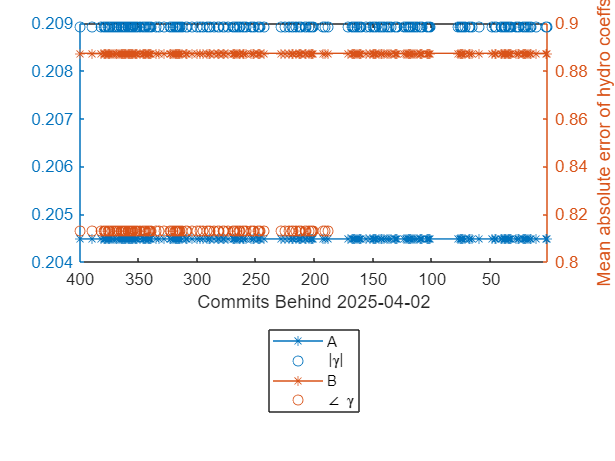


x = 1:N;
names = {'A','B','|\gamma|','\angle \gamma'};

commit_keep = any(~isnan(hydro_error));

figure
for i=1:4
    if i==1 || i==3
        yyaxis left
    else
        yyaxis right
    end
    if i==1 || i==2
        linespec = '*-';
    else
        linespec = 'o';
    end
    plot(x(commit_keep), hydro_error(i,commit_keep), linespec,'DisplayName',names{i})
    hold on
end
xlabel(['Commits Behind ' end_date])
ylabel('Mean absolute error of hydro coeffs')
legend('location','southoutside')

set(gca, 'XDir','reverse')

% commits of interest
plot_special = false;
if plot_special
    special.commits = {'35dd22a',          'e43e255',                           '1f3a7c9',                   'e7d6a47',                       '8d4d72b', '8afb07a',  'abc66f4',           '14e825b',       '06c4456',             'c672caf',           '9346984',           '9f37e95',                      'a12665e'};
    special.note = {'fix dispersion error','introduce w-dependent fudge factor','introduce dispersion error','remove w-fudge and power ratio','set h=45','set h=100','turn multibody off','wecsim matched','finite depth haskind','drag less converged','m scale 1.1 to 1.0','merge writing into force sat','switch from writing to readme'};
    [idx1,idx2] = ismember(hash_cell,special.commits);
    tmp1 = find(idx1);
    tmp2 = zeros(size(tmp1));
    tmp2(idx2(idx2~=0)) = tmp1;
    special.commit_idx = tmp2;
    
    [~,sort_idx] = sort(special.commit_idx,'descend');
    special_sorted = structfun(@(f) f(sort_idx), special, 'UniformOutput',false);
    
    for i=1:length(special.commits)
        idx = special_sorted.commit_idx(i);
        day = date_cell{idx};
        name = [special_sorted.commits{i} ' ' day ': ' special_sorted.note{i}];
        plot([1 1]*idx, [0 1],'DisplayName',name)
    end
end

k = find(commit_keep);
xlim([min(k) max(k)])

function value = extract_actual_value(annotation)

    % Match everything after "Actual Value:" up to newline
    line_pattern = 'Actual Value:\s*([^\r\n]*)';
    line_match = regexp(annotation, line_pattern, 'tokens', 'once');

    if isempty(line_match)
        value = NaN;
        return
    end

    number_str = line_match{1};

    % Match floats, scientific notation, or ±Inf
    num_pattern = '[-+]?(?:\d*\.\d+|\d+)(?:[eE][-+]?\d+)?|[-+]?Inf';

    matches = regexp(number_str, num_pattern, 'match');

    value = str2double(matches(:));  % column vector

end